# 034IN - FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL - A.Y. 2024-2025

# MATLAB GRADER - Laplace Transform Applications

# Problem 1 - Laplace Transforms of Functions in the Time-Domain

**Tag List:** `[STANDARD ASSESSMENT] [PARTIAL CREDIT] [SYMBOLIC] [PRETEST]`

Determine the **Laplace transform** expression $$F(s)$$ for the following mathematical functions in the time domain $$f(t)$$: 

- 
$$f(t)=8t+2$$


- 
$$g(t)=5 \frac{df(t)}{dt}$$


- 
$$x(t)=5\int_0^{t} f(\tau)\,d\,\tau$$


using Matlab's **Symbolic Toolbox**.

Your solution should:

- Create the symbolic variable named **t**, that corresponds to the independent variable *time, *the *symbolic variable *`tau` and the *symbolic variable named ****s***, corresponding to the independent complex variable in the Laplace transform domain.

- Assume that $t \ge 0$ and $\tau \ge 0$.

- Create  symbolic functions for the functions $f(t),\,g(t),\,x(t)$, named **f(t)**. **g(t)**, and **x(t)** .

- Assign to the symbolic functions **f(t)**. **g(t)**, and **x(t)** the expressions given above.

- Evaluate the three Laplace transform expressions, making use of the available Symbolic Toolbox commands and functions .

- Assing the resulting Laplace transforms to the symbolic functions named **F(s)**, **G(s)** and **X(s)**, corresponding respectively to the Laplace transform expressions for the time-domain functions $f(t),\,g(t),\,x(t)$.

## Solution

% ---- 1st bullet point <<--
syms t s tau

% ---- 2nd bullet point <<--
assume(t>=0)
assumeAlso(tau>=0) % refer to the online documentation and help for details about assume() and assumeAlso()


% --- NOT requested! It's a way to obtain
%     a detailed description of ALL the 
%     active assumptions, so it could be helpful to tyou
%     to debug the code (i.e answering to:
%     "Did you insert all the required assumptions?")
assumptions   

$$ans = \left[\begin{array}{cc} 0\leq t & 0\leq \tau \end{array}\right]$$

% ---- 3rd bullet point <<--
syms f(t) g(t) x(t) 

% ---- 4th bullet point <<--
f(t) = 8 * t + 2

$$f(t) = 8\,t+2$$

g(t) = 5 * diff(f(t),1)

$$g(t) = 40$$

### Remark: a Common Syntax Error

Pay attention to the following line of code

It seems to be a correct line of code; indeed, you don't receive any error message if you run this section, BUT this code contains a mistake! Why?

Let's solve the integral that is the definition of the causal function $x(t)$ by hand:


$$x(t) = 5\int_0^{t} f(\tau)\,d\,\tau = 5\int_0^{t} \big[8\,\tau+2 \big]\, d \tau = \left. \big(10\, \tau \big) \right\vert^{t}_{0} + \left. \big(20 \, \tau^2 \big) \right\vert^{t}_{0} = 10\,t+20\,t^2 = 10\,t\,\left(2\,t+1\right)$$


 Let's execute this (wrong) portion of code:

x(t) = 5 * int(f,tau,0,t)

$$x(t) = 10\,t\,\left(4\,t+1\right)$$

The result is different!! Why?

Have a look to the syntax of the command `int`:

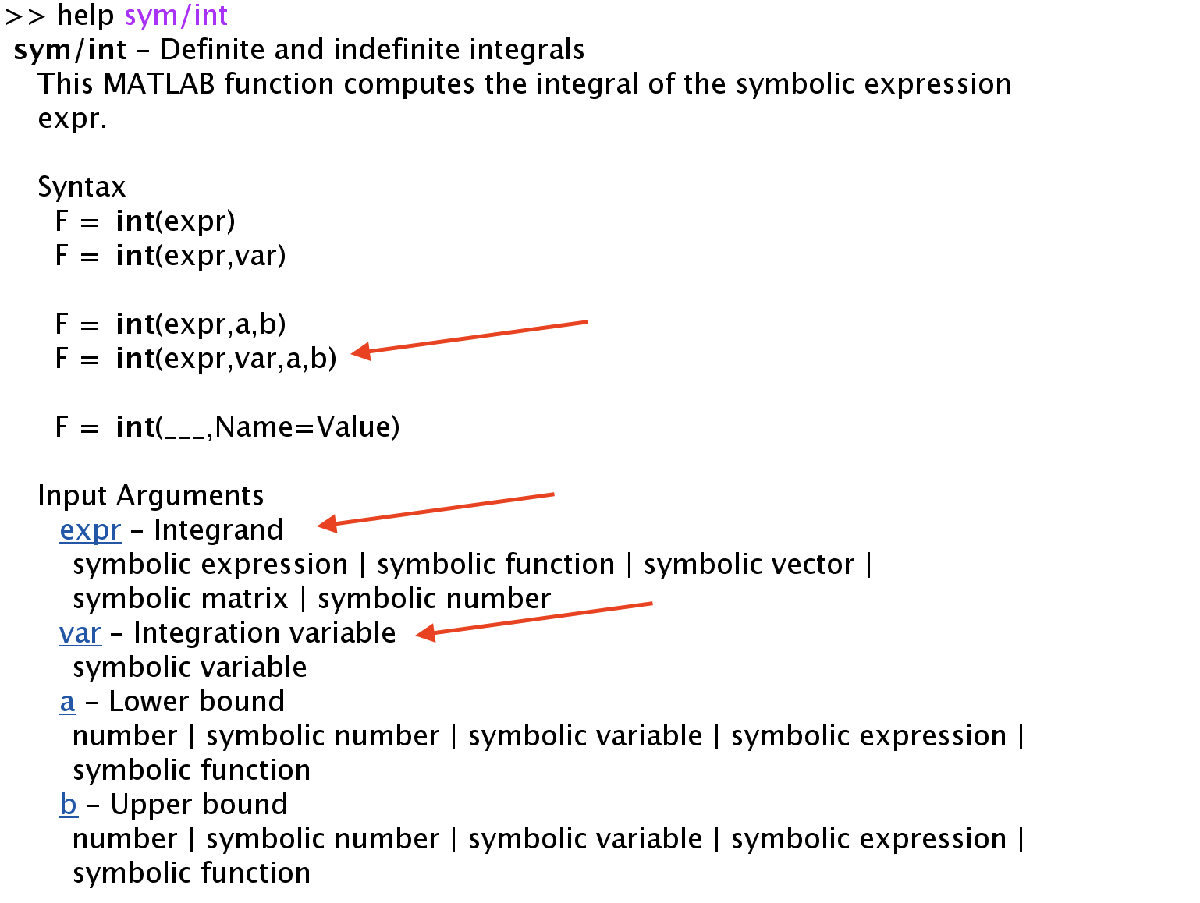

Using the (wrong) code we are analysing, the integrand expression, i.e. the symbolic function `f, `is depending on the variable` t`, not `tau`:

disp(f)

$$8\,t+2$$

Thus, we are asking to **compute a slightly different definite integral**, defined as follows


$$5\int_0^{t} \big[8\,t+2 \big]\, d \tau = 10\,\left(4\,t+1\right)\,\displaystyle \int_0^{t} d\,\tau = 10\,t\,\left(4\,t+1\right)$$


**Note**: the integrand expression is indeed INDEPENDENT of the integration variable $\tau$.  This fact explains the different (wrong) results and the poor marks provided by the MATLAB Grader.

For a complete overview fo the command `int` capabilities:

help sym/int

 sym/int - Definite and indefinite integrals
    This MATLAB function computes the integral of the symbolic expression
    expr.

    Syntax
      F = int(expr)
      F = int(expr,var)

      F = int(expr,a,b)
      F = int(expr,var,a,b)

      F = int(___,Name=Value)

    Input Arguments
      expr - Integrand
        symbolic expression | symbolic function | symbolic vector |
        symbolic matrix | symbolic number
      var - Integration variable
        symbolic variable
      a - Lower bound
        number | symbolic number | symbolic variable | symbolic expression |
        symbolic function
    

### Solution - Part 2

Let's continue, applying the command `int` in the proper way:

% --- final part of the answer to the 4th bullet point assignment <<--
x(t) = 5 * int(f(tau),tau,0,t)

$$x(t) = 10\,t\,\left(2\,t+1\right)$$

% --- the 5th bullet point <<---
syms F(s) G(s) X(s) 

F(s) = laplace(f(t))
G(s) = laplace(g(t))
X(s) = laplace(x(t))

% --->>> end of the code <<---